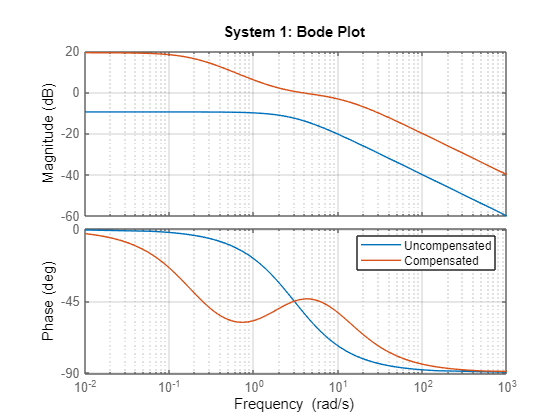

% ============================================================
%  NAME: Joshua Muthenya Wambua
%  REG NO: EG209/109705/22
%  DATE: 09-Nov-2025
%  Objective:
%     To design and analyze a lead–lag compensated control system
%     for improved transient and steady-state performance.
% ============================================================

clc; clear; close all;

%% ------------------------------------------------
%  Common definitions
% ------------------------------------------------
s = tf('s'); % Laplace variable

% Lead compensator
C_lead = 10 * (s + 3) / (s + 11);

% Lag compensator
C_lag = (s + 2) / (s + 0.2);

% Combined lead–lag compensator
C_T = C_lead * C_lag;

%% ============================================================
% SYSTEM 1 : G(s) = s / [ s(s+3) ]
%% ============================================================

G1 = s/(s*(s+3));

T_uncomp = feedback(G1,1);
T_comp   = feedback(C_T*G1,1);

figure('Name','Bode Plot Comparison','NumberTitle','off');
bode(G1, C_T*G1); grid on;
title('System 1: Bode Plot');
legend('Uncompensated','Compensated');

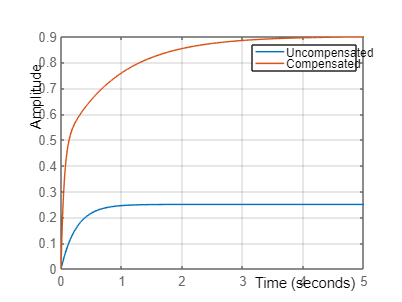


figure('Name','Step Response Comparison','NumberTitle','off');
step(T_uncomp, T_comp, 5); grid on;
title('System 1: Step Response');
legend('Uncompensated','Compensated');

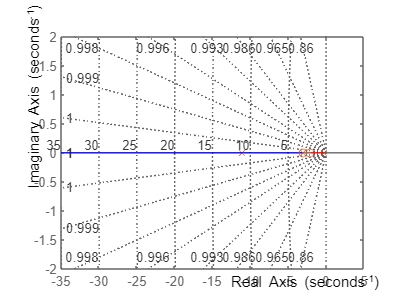


figure('Name','Root Locus Comparison','NumberTitle','off');
rlocus(G1); hold on; rlocus(C_T*G1); grid on;
title('System 1: Root Locus');

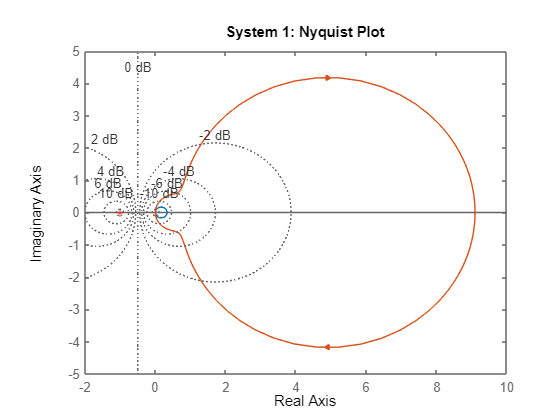


figure('Name','Nyquist Plot Comparison','NumberTitle','off');
nyquist(G1, C_T*G1); grid on;
title('System 1: Nyquist Plot');


disp('SYSTEM 1 PERFORMANCE');

SYSTEM 1 PERFORMANCE


disp(stepinfo(T_uncomp));

         RiseTime: 0.5493
    TransientTime: 0.9780
     SettlingTime: 0.9780
      SettlingMin: 0.2261
      SettlingMax: 0.2500
        Overshoot: 0
       Undershoot: 0
             Peak: 0.2500
         PeakTime: 2.6365



disp(stepinfo(T_comp));

         RiseTime: 1.3980
    TransientTime: 2.8647
     SettlingTime: 2.8647
      SettlingMin: 0.8112
      SettlingMax: 0.9002
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9002
         PeakTime: 5.8621



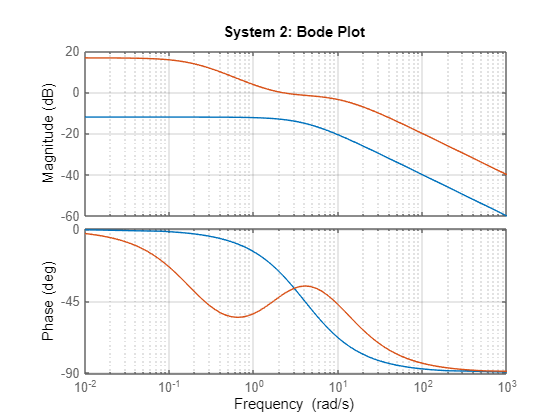


%% ============================================================
% SYSTEM 2 : G(s) = s / [ s(s+4) ]
%% ============================================================

G2 = s/(s*(s+4));

T_uncomp = feedback(G2,1);
T_comp   = feedback(C_T*G2,1);

figure; bode(G2, C_T*G2); grid on; title('System 2: Bode Plot');

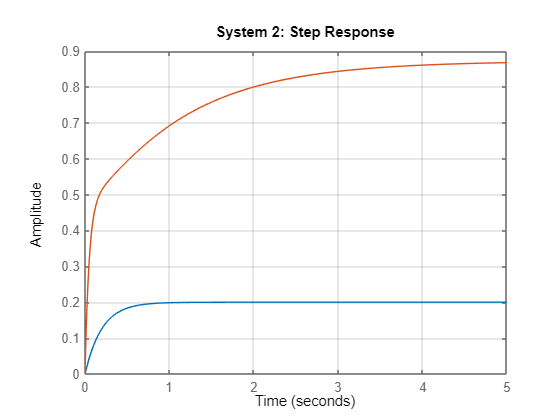

figure; step(T_uncomp, T_comp, 5); grid on; title('System 2: Step Response');

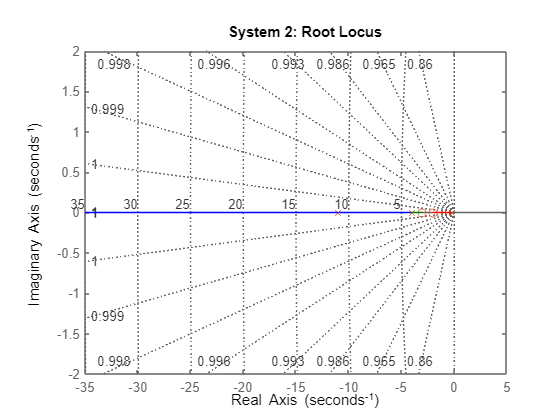

figure; rlocus(G2); hold on; rlocus(C_T*G2); grid on; title('System 2: Root Locus');

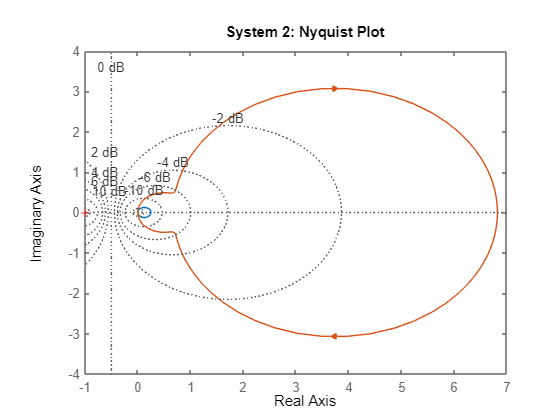

figure; nyquist(G2, C_T*G2); grid on; title('System 2: Nyquist Plot');


disp('SYSTEM 2 PERFORMANCE');

SYSTEM 2 PERFORMANCE


disp(stepinfo(T_uncomp));

         RiseTime: 0.4394
    TransientTime: 0.7824
     SettlingTime: 0.7824
      SettlingMin: 0.1809
      SettlingMax: 0.2000
        Overshoot: 0
       Undershoot: 0
             Peak: 0.2000
         PeakTime: 2.1092



disp(stepinfo(T_comp));

         RiseTime: 1.7871
    TransientTime: 3.5433
     SettlingTime: 3.5433
      SettlingMin: 0.7852
      SettlingMax: 0.8700
        Overshoot: 0
       Undershoot: 0
             Peak: 0.8700
         PeakTime: 5.8334



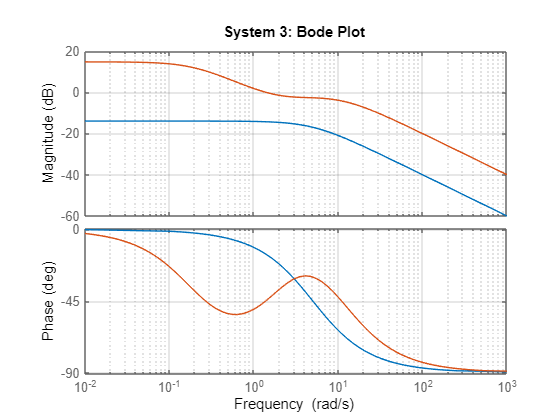


%% ============================================================
% SYSTEM 3 : G(s) = s / [ s(s+5) ]
%% ============================================================

G3 = s/(s*(s+5));

T_uncomp = feedback(G3,1);
T_comp   = feedback(C_T*G3,1);

figure; bode(G3, C_T*G3); grid on; title('System 3: Bode Plot');

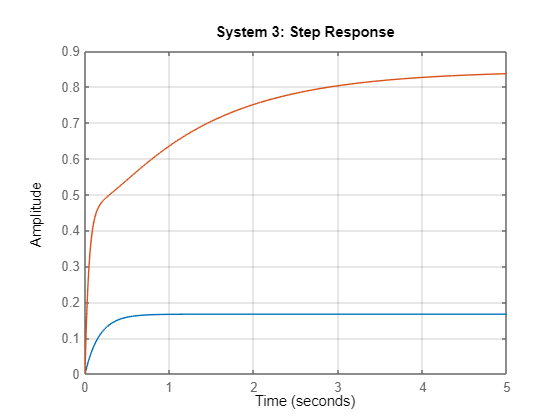

figure; step(T_uncomp, T_comp, 5); grid on; title('System 3: Step Response');

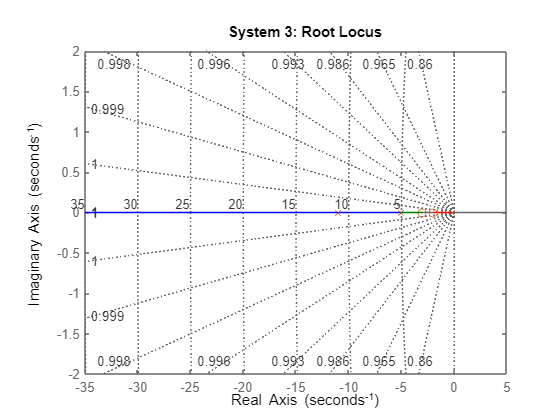

figure; rlocus(G3); hold on; rlocus(C_T*G3); grid on; title('System 3: Root Locus');

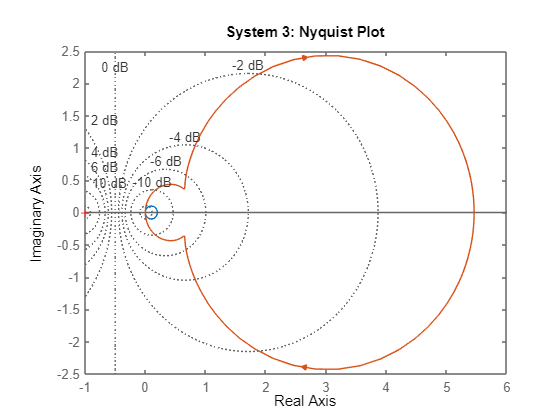

figure; nyquist(G3, C_T*G3); grid on; title('System 3: Nyquist Plot');


disp('SYSTEM 3 PERFORMANCE');

SYSTEM 3 PERFORMANCE


disp(stepinfo(T_uncomp));

         RiseTime: 0.3662
    TransientTime: 0.6520
     SettlingTime: 0.6520
      SettlingMin: 0.1508
      SettlingMax: 0.1667
        Overshoot: 0
       Undershoot: 0
             Peak: 0.1667
         PeakTime: 1.7576



disp(stepinfo(T_comp));

         RiseTime: 2.1209
    TransientTime: 4.1168
     SettlingTime: 4.1168
      SettlingMin: 0.7606
      SettlingMax: 0.8448
        Overshoot: 0
       Undershoot: 0
             Peak: 0.8448
         PeakTime: 9.0891



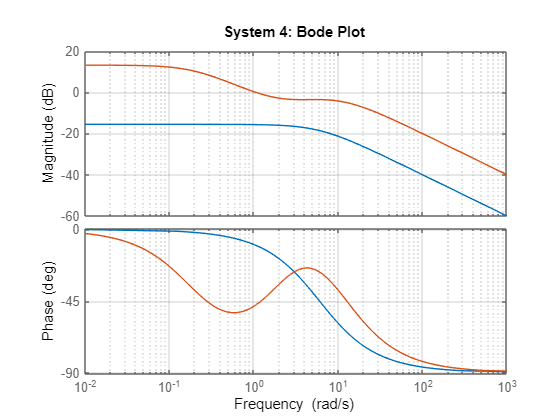


%% ============================================================
% SYSTEM 4 : G(s) = s / [ s(s+6) ]
%% ============================================================

G4 = s/(s*(s+6));

T_uncomp = feedback(G4,1);
T_comp   = feedback(C_T*G4,1);

figure; bode(G4, C_T*G4); grid on; title('System 4: Bode Plot');

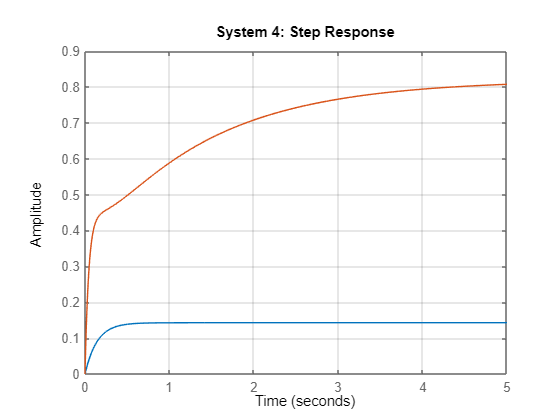

figure; step(T_uncomp, T_comp, 5); grid on; title('System 4: Step Response');

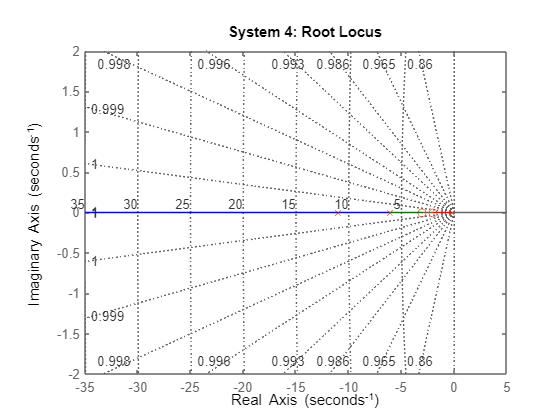

figure; rlocus(G4); hold on; rlocus(C_T*G4); grid on; title('System 4: Root Locus');

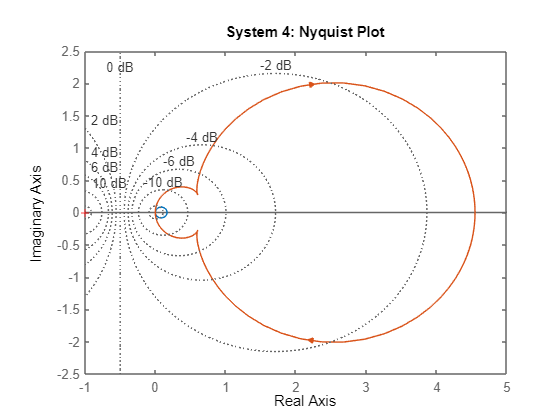

figure; nyquist(G4, C_T*G4); grid on; title('System 4: Nyquist Plot');


disp('SYSTEM 4 PERFORMANCE');

SYSTEM 4 PERFORMANCE


disp(stepinfo(T_uncomp));

         RiseTime: 0.3139
    TransientTime: 0.5589
     SettlingTime: 0.5589
      SettlingMin: 0.1292
      SettlingMax: 0.1429
        Overshoot: 0
       Undershoot: 0
             Peak: 0.1429
         PeakTime: 1.5065



disp(stepinfo(T_comp));

         RiseTime: 2.4179
    TransientTime: 4.6264
     SettlingTime: 4.6264
      SettlingMin: 0.7379
      SettlingMax: 0.8183
        Overshoot: 0
       Undershoot: 0
             Peak: 0.8183
         PeakTime: 8.0283



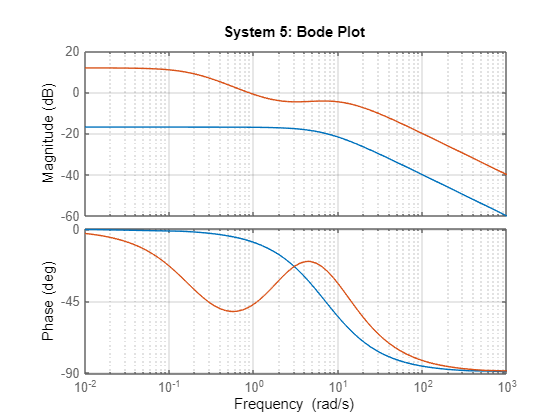


%% ============================================================
% SYSTEM 5 : G(s) = s / [ s(s+7) ]
%% ============================================================

G5 = s/(s*(s+7));

T_uncomp = feedback(G5,1);
T_comp   = feedback(C_T*G5,1);

figure; bode(G5, C_T*G5); grid on; title('System 5: Bode Plot');

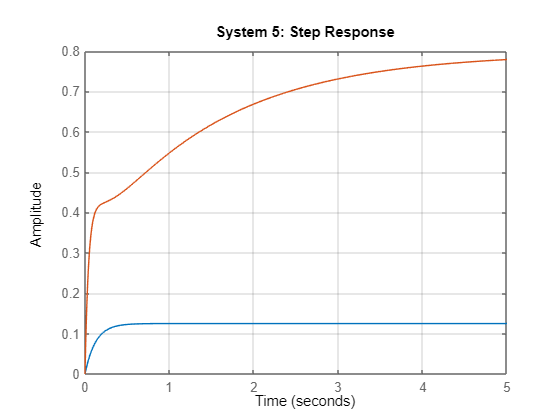

figure; step(T_uncomp, T_comp, 5); grid on; title('System 5: Step Response');

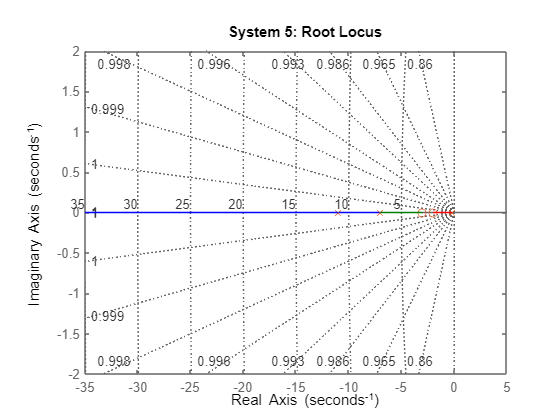

figure; rlocus(G5); hold on; rlocus(C_T*G5); grid on; title('System 5: Root Locus');

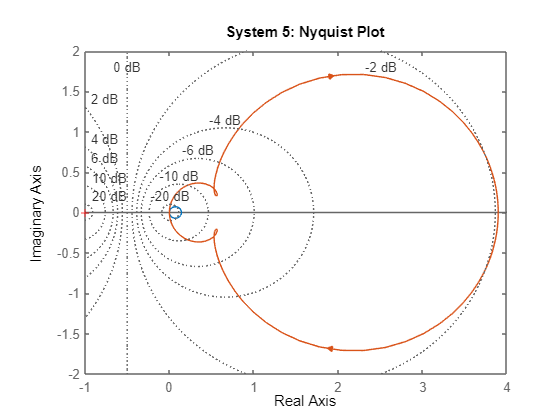

figure; nyquist(G5, C_T*G5); grid on; title('System 5: Nyquist Plot');


disp('SYSTEM 5 PERFORMANCE');

SYSTEM 5 PERFORMANCE


disp(stepinfo(T_uncomp));

         RiseTime: 0.2746
    TransientTime: 0.4890
     SettlingTime: 0.4890
      SettlingMin: 0.1131
      SettlingMax: 0.1250
        Overshoot: 0
       Undershoot: 0
             Peak: 0.1250
         PeakTime: 1.3182



disp(stepinfo(T_comp));

         RiseTime: 2.6883
    TransientTime: 5.0895
     SettlingTime: 5.0895
      SettlingMin: 0.7163
      SettlingMax: 0.7940
        Overshoot: 0
       Undershoot: 0
             Peak: 0.7940
         PeakTime: 8.3248



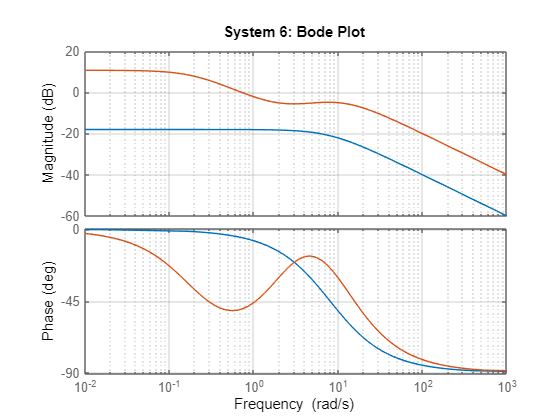


%% ============================================================
% SYSTEM 6 : G(s) = s / [ s(s+8) ]
%% ============================================================

G6 = s/(s*(s+8));

T_uncomp = feedback(G6,1);
T_comp   = feedback(C_T*G6,1);

figure; bode(G6, C_T*G6); grid on; title('System 6: Bode Plot');

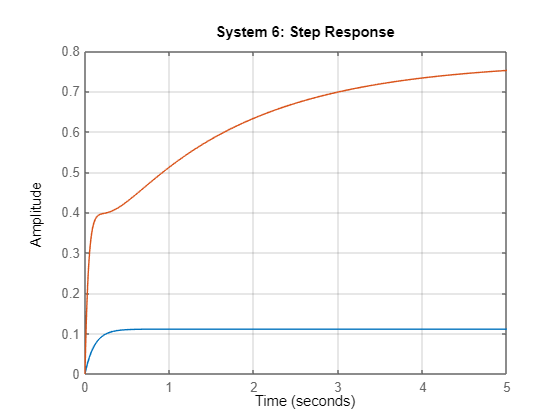

figure; step(T_uncomp, T_comp, 5); grid on; title('System 6: Step Response');

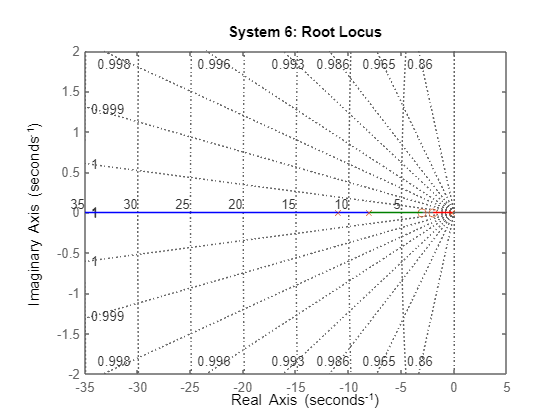

figure; rlocus(G6); hold on; rlocus(C_T*G6); grid on; title('System 6: Root Locus');

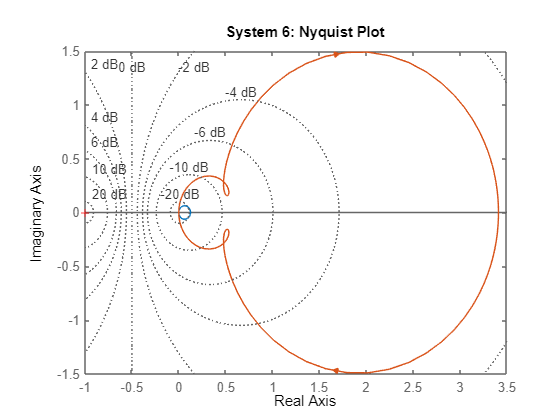

figure; nyquist(G6, C_T*G6); grid on; title('System 6: Nyquist Plot');


disp('SYSTEM 6 PERFORMANCE');

SYSTEM 6 PERFORMANCE


disp(stepinfo(T_uncomp));

         RiseTime: 0.2441
    TransientTime: 0.4347
     SettlingTime: 0.4347
      SettlingMin: 0.1005
      SettlingMax: 0.1111
        Overshoot: 0
       Undershoot: 0
             Peak: 0.1111
         PeakTime: 1.1718



disp(stepinfo(T_comp));

         RiseTime: 2.9375
    TransientTime: 5.5159
     SettlingTime: 5.5159
      SettlingMin: 0.6960
      SettlingMax: 0.7730
        Overshoot: 0
       Undershoot: 0
             Peak: 0.7730
         PeakTime: 12.6369



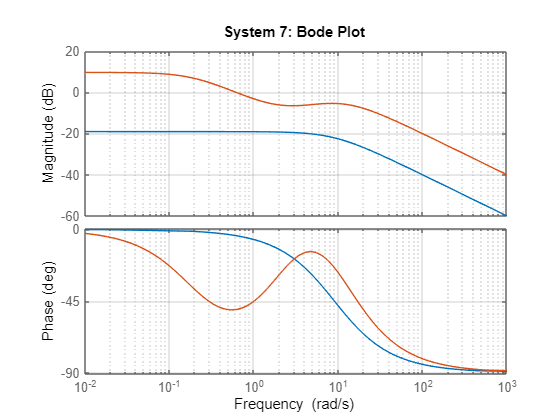


%% ============================================================
% SYSTEM 7 : G(s) = s / [ s(s+9) ]
%% ============================================================

G7 = s/(s*(s+9));

T_uncomp = feedback(G7,1);
T_comp   = feedback(C_T*G7,1);

figure; bode(G7, C_T*G7); grid on; title('System 7: Bode Plot');

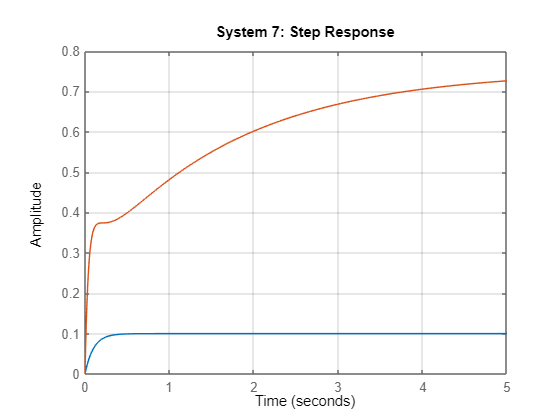

figure; step(T_uncomp, T_comp, 5); grid on; title('System 7: Step Response');

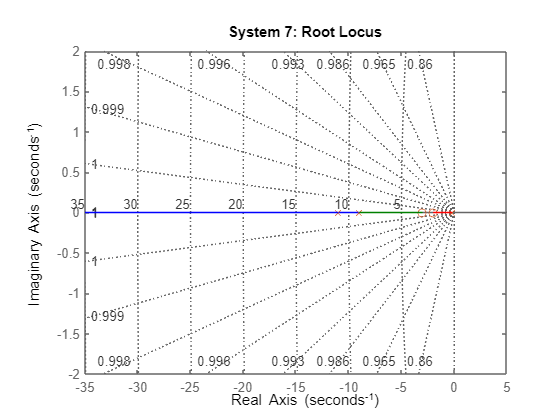

figure; rlocus(G7); hold on; rlocus(C_T*G7); grid on; title('System 7: Root Locus');

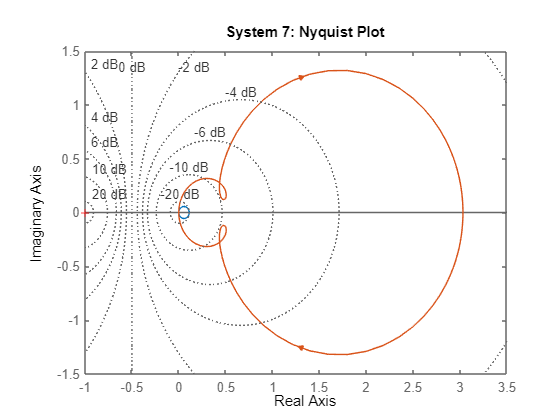

figure; nyquist(G7, C_T*G7); grid on; title('System 7: Nyquist Plot');


disp('SYSTEM 7 PERFORMANCE');

SYSTEM 7 PERFORMANCE


disp(stepinfo(T_uncomp));

         RiseTime: 0.2197
    TransientTime: 0.3912
     SettlingTime: 0.3912
      SettlingMin: 0.0905
      SettlingMax: 0.1000
        Overshoot: 0
       Undershoot: 0
             Peak: 0.1000
         PeakTime: 1.0546



disp(stepinfo(T_comp));

         RiseTime: 3.1690
    TransientTime: 5.9116
     SettlingTime: 5.9116
      SettlingMin: 0.6768
      SettlingMax: 0.7504
        Overshoot: 0
       Undershoot: 0
             Peak: 0.7504
         PeakTime: 9.8021



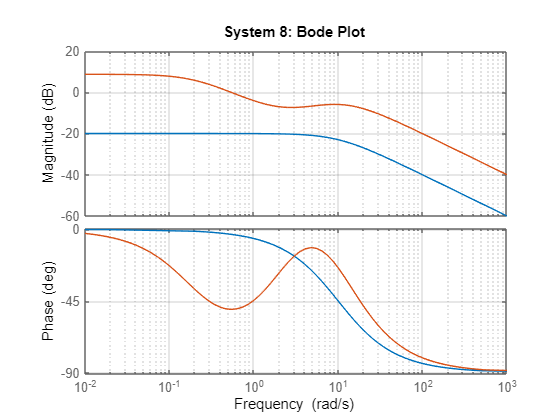


%% ============================================================
% SYSTEM 8 : G(s) = s / [ s(s+10) ]
%% ============================================================

G8 = s/(s*(s+10));

T_uncomp = feedback(G8,1);
T_comp   = feedback(C_T*G8,1);

figure; bode(G8, C_T*G8); grid on; title('System 8: Bode Plot');

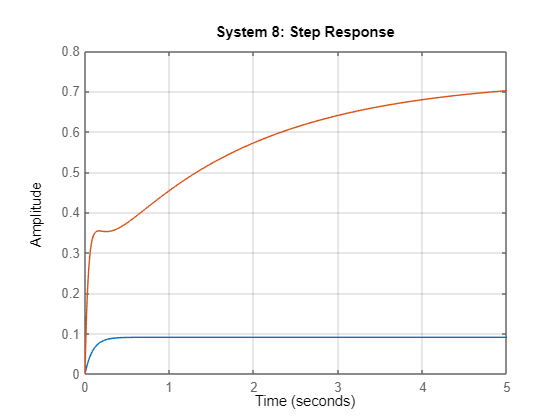

figure; step(T_uncomp, T_comp, 5); grid on; title('System 8: Step Response');

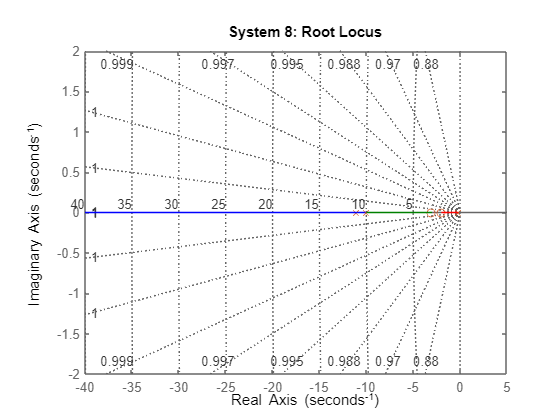

figure; rlocus(G8); hold on; rlocus(C_T*G8); grid on; title('System 8: Root Locus');

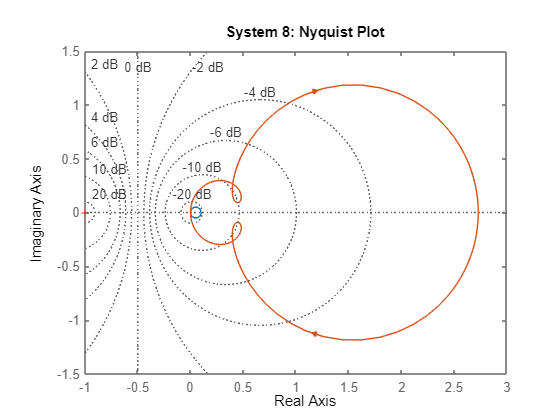

figure; nyquist(G8, C_T*G8); grid on; title('System 8: Nyquist Plot');


disp('SYSTEM 8 PERFORMANCE');

SYSTEM 8 PERFORMANCE


disp(stepinfo(T_uncomp));

         RiseTime: 0.1997
    TransientTime: 0.3556
     SettlingTime: 0.3556
      SettlingMin: 0.0822
      SettlingMax: 0.0909
        Overshoot: 0
       Undershoot: 0
             Peak: 0.0909
         PeakTime: 0.9587



disp(stepinfo(T_comp));

         RiseTime: 3.3853
    TransientTime: 6.2810
     SettlingTime: 6.2810
      SettlingMin: 0.6586
      SettlingMax: 0.7305
        Overshoot: 0
       Undershoot: 0
             Peak: 0.7305
         PeakTime: 10.7433

